% clearvars -except current_faulty current_healthy time_healthy time_faulty current_exp_healthy time_exp_halthy current_exp_faulty time_exp_faulty PSD_dB_exp_h PSD_dB_exp_f PSD_dB PSD_dB_f f f2 f_exp_h f_exp_f;
clc;
no_of_data = 1;
[timeData, currentData] = readDataFromFiles(no_of_data);

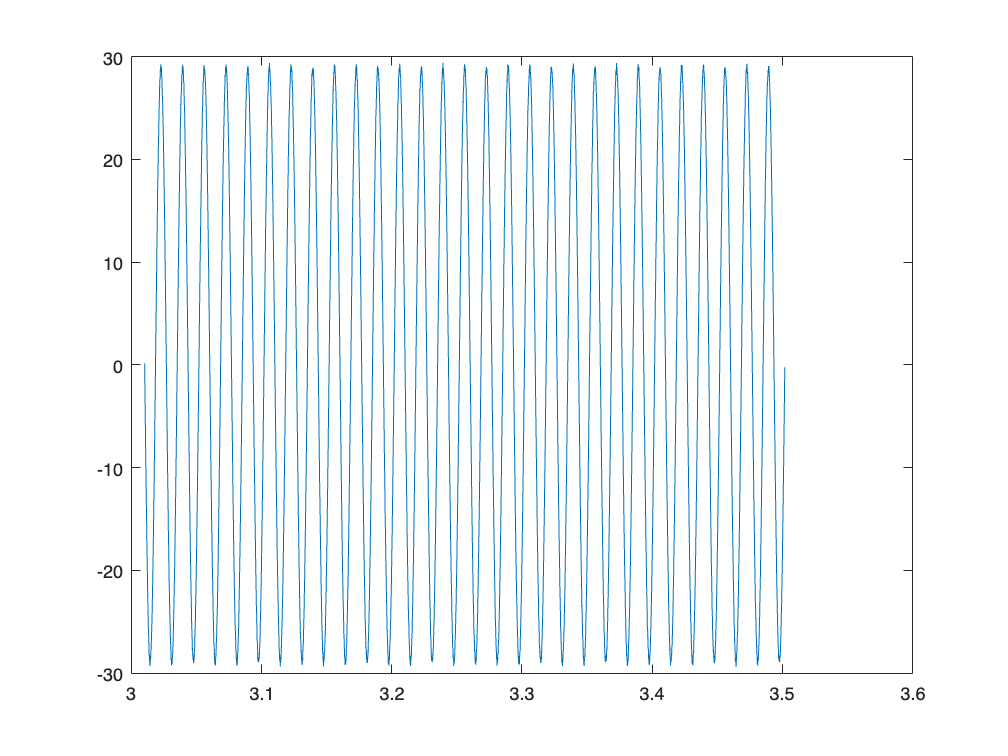

Unrecognized function or variable 'calculate_psd'.


% Define individual values for threshold time and number of zero crossings
  % threshold_time_values = [2.5, 2.5, 2.5, 2.5, 2.5];  
 threshold_time_values = [3.00392, 3.0122, 3.0122, 1, 1]; 
 % num_zero_crossings_values = [4200, 1000, 1800, 3000, 5300];  
 num_zero_crossings_values = [60, 60, 5000, 300, 300]; 
% num_zero_crossings_values = [60, 60, 60, 60, 60];  
segment_fraction = 0.5;

% Pre-allocate cell arrays to store the results
f_exp = cell(1, no_of_data);
PSD_dB_exp = cell(1, no_of_data);
P_at_60Hz = cell(1, no_of_data);
time_lc_all = cell(1, no_of_data);  % Cell array to store time data from plot_cycles
current_lc_all = cell(1, no_of_data);  % Cell array to store current data from plot_cycles


for i = 1:no_of_data
    % Extract time and current data for the current iteration
    time_exp = timeData{i};
    current_exp = currentData{i};
    
    % Get the individual threshold time and number of zero crossings for the current file
    threshold_time = threshold_time_values(i);
    num_zero_crossings = num_zero_crossings_values(i);
    
    % Call plot_cycles
    [time_lc, current_lc] = plot_cycles(time_exp, current_exp, threshold_time, num_zero_crossings);
    
    % Store the time and current data from plot_cycles
    time_lc_all{i} = time_lc;
    current_lc_all{i} = current_lc;
    figure;
    % Plot the results of plot_cycles
    plot(time_lc, current_lc);
    
    % Call calculate_psd
    [f_exp{i}, PSD_dB_exp{i}, P_at_60Hz{i}] = calculate_psd(time_lc, current_lc, segment_fraction);
    
end

% Assume segment_fraction is already defined
segment_fraction = 0.5;

% Pre-allocate cell arrays to store the results
f_exp = cell(1, no_of_data);
PSD_dB_exp = cell(1, no_of_data);
P_at_60Hz = cell(1, no_of_data);

for i = 1:no_of_data
    % Get the individual time and current data arrays for the current file
    time_lc = time_lc_all{i};
    current_lc = current_lc_all{i};
    
    % Call calculate_psd
    [f_exp{i}, PSD_dB_exp{i}, P_at_60Hz{i}] = calculate_psd(time_lc, current_lc, segment_fraction);
    
end
label = ['1', '2', '3', '4'];
% for i = 2:no_of_data

    plotPSD(PSD_dB_exp{1}, f_exp{1}, PSD_dB_exp{2}, f_exp{2}, PSD_dB_exp{3}, f_exp{3}, true, [700, 850], 'Healthy', label(i-1));

% end
target_frequency = 732;

for i = 1:length(f_exp)
    % Get the current frequency array
    current_f_exp = f_exp{i};
    
    % Find the index where f_exp is nearest to 780
    [~, idx] = min(abs(current_f_exp - target_frequency));
    
    % Get the corresponding value from PSD_dB_exp
    current_PSD_dB_exp = PSD_dB_exp{i};
    value_at_idx = current_PSD_dB_exp(idx);
    
    % Display the value
    disp(['For file ', num2str(i), ', the value of PSD_dB_exp at the nearest frequency to 780 is: ', num2str(value_at_idx)]);
end

function [timeData, currentData] = readDataFromFiles(numFiles)
    % Pre-allocate cell arrays to store the data
    timeData = cell(1, numFiles);
    currentData = cell(1, numFiles);

    % Loop through the process of selecting and reading the data for each file
    for i = 1:numFiles
        [filename, pathname] = uigetfile({'*.xls;*.xlsx', 'Excel Files (*.xls, *.xlsx)'; ...
                                           '*.*', 'All Files (*.*)'}, ...
                                           sprintf('Select Excel file %d', i));
        fullpath = fullfile(pathname, filename);
        dataTable = readtable(fullpath, 'Range', 'A:B');
        dataMatrix = table2array(dataTable);
        timeData{i} = dataMatrix(:, 1);
        currentData{i} = dataMatrix(:, 2);
    end
end

